# HW08

## state space model definition


A = [-0.04167   0        -0.0058;
      0.0217   -0.24      0.0058;
      0        100       -2.4];

B = [5.2; -5.2; 0];

C = [0 0 1];

D = 0;

sys = ss(A, B, C, D);


## conversion to transfer function

G = tf(sys)

G =
 
            -520 s - 10.38
  -----------------------------------
  s^3 + 2.682 s^2 + 0.106 s + 0.01242
 
Continuous-time transfer function.
Model Properties


p = pole(sys)

p =   -0.0192 + 0.0658i
  -0.0192 - 0.0658i
  -2.6433 + 0.0000i


z = zero(sys)

z = -0.0200

## using ackerman method

% Definice rozšířených matic A_big a B_big
Abig = [-0.04167  0       -0.0058  0;
         0.0217  -0.24     0.0058  0;
         0       100      -2.4     0;
         0       0        -1       0];

Bbig = [5.2; -5.2; 0; 0];

% Dva dominantní póly z přechodové specifikace
dominant_poles = roots([1 0.08 0.046]); 

% Přidání dalších pólů: jeden v nule (integrátor) a jeden hodně vlevo (např. -5)
additional_poles = [-0.02; -100];

% Celkový seznam pólů
desired_poles = [dominant_poles; additional_poles]

desired_poles = 1.0e+02 *

  -0.0004 + 0.0021i
  -0.0004 - 0.0021i
  -0.0002 + 0.0000i
  -1.0000 + 0.0000i



% Výpočet zesílení pomocí Ackermannovy metody
K = acker(Abig, Bbig, desired_poles);

% Výpis výsledku
disp('Zesílení K:');

Zesílení K:


disp(K);

   -0.0066  -18.7409    0.4342    0.0089



## step response with the state gain regulator

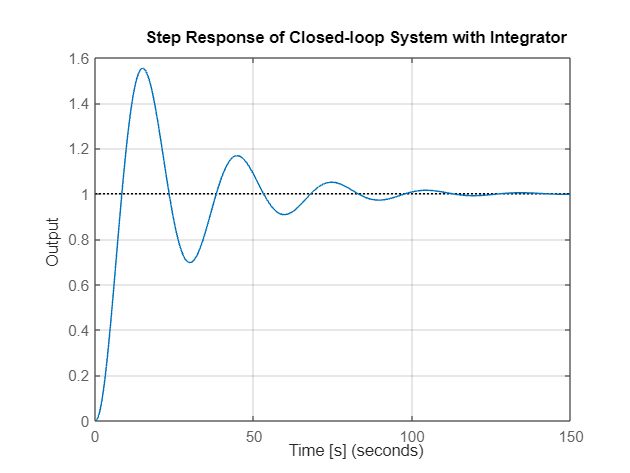

% Předpokládám, že máš:
% - A (3x3)
% - B (3x1)
% - C (1x3)
% - D (skalar, 0)
% - K (1x4), kde K(1:3) je na stavy, K(4) na integrátor


% Rozdělení zesílení
K1 = K(1:3); % zesílení na stavové proměnné
KI = K(4);  % zesílení na integrátor

% Sestavení nové uzavřené matice A podle obrázku
Acl = [A - B*K1,   -B*KI;
       -C,         0];

% Sestavení nové matice B (vstup ovlivňuje jen integrátor)
Bcl = [0; 0; 0; 1];

% Sestavení nové matice C (výstup závisí jen na x, ne na integrátor)
Ccl = [C, 0];

% Matice D zůstává 0
Dcl = 0;

% Vytvoření nového uzavřeného systému
sys_cl = ss(Acl, Bcl, Ccl, Dcl);

% Definice času simulace (0 až 150 sekund)
t = linspace(0, 150, 1000); % 1000 bodů mezi 0 a 150

% Simulace skokové odezvy s časovým vektorem
step(sys_cl, t);
title('Step Response of Closed-loop System with Integrator');
xlabel('Time [s]');
ylabel('Output');
grid on;

disp(eig(Acl));

-100.0000 + 0.0000i
  -0.0400 + 0.2107i
  -0.0400 - 0.2107i
  -0.0200 + 0.0000i

